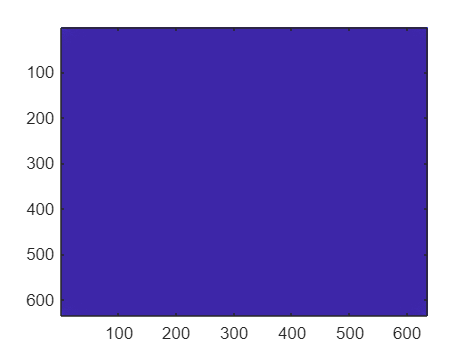

img = imread('squaredog.jpg');

R = img(:,:,1);
G = img(:,:,2);
B = img(:,:,3);

R = fft2(R);
M = abs(R);
M = M + imnoise(M, "gaussian")*0.1;
P = angle(R);

R = M.*exp(1i.*P);
R = uint8(ifft2(R));



G = fft2(G);
M = abs(G);
M = M + imnoise(M, "gaussian")*0.1;
P = angle(G);

G = M.*exp(1i.*P);
G = uint8(ifft2(G));


B = fft2(B);
M = abs(B);
M = M + imnoise(M, "gaussian")*0.1;
P = angle(B);

B = M.*exp(1i.*P);
B = uint8(ifft2(B));


imagesc(M);

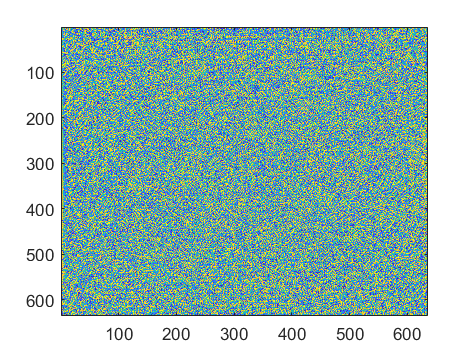

imagesc(P);

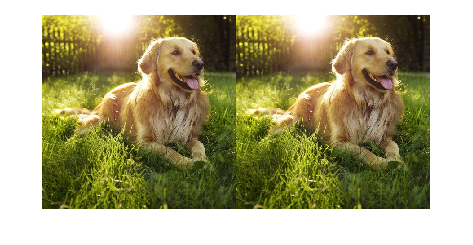

outImg = cat(3,R,G,B);

montage({img,outImg});